## PART 1: KINEMATICS

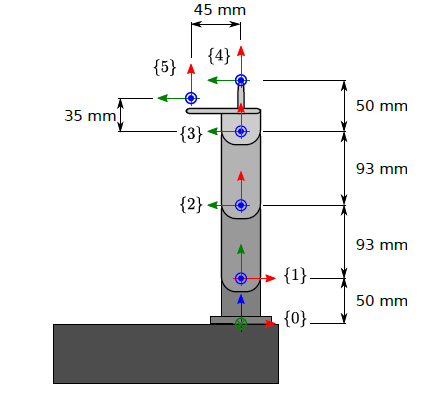

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;
% % Uncomment for symbolic representation
syms t1 t2 t3 t4 

% {0} -> {1}
T01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) L01;
       0 0 0 1];
% {1} -> {2}
T12 = [cos(t2) -sin(t2) 0 L12;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];
% {2} -> {3}
T23 = [1 0 0 L23;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {4}
T34 = [1 0 0 L34;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {5}
T35 = [1 0 0 L35;
       0 1 0 L45;
       0 0 1 0;
       0 0 0 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 143\,\cos\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 143\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 143\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \left(\begin{array}{cccc} \cos\left(t_{2}\right) & -\sin\left(t_{2}\right) & 0 & 128\,\cos\left(t_{2}\right)-45\,\sin\left(t_{2}\right)+93\\ \cos\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{1}\right)\,\cos\left(t_{2}\right) & -\sin\left(t_{1}\right) & 45\,\cos\left(t_{1}\right)\,\cos\left(t_{2}\right)+128\,\cos\left(t_{1}\right)\,\sin\left(t_{2}\right)\\ \sin\left(t_{1}\right)\,\sin\left(t_{2}\right) & \cos\left(t_{2}\right)\,\sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 45\,\cos\left(t_{2}\right)\,\sin\left(t_{1}\right)+128\,\sin\left(t_{1}\right)\,\sin\left(t_{2}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

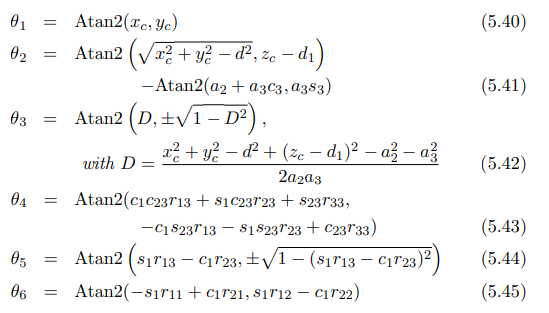

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



t1 = atan2(xc,yc);

t3 = atan2(D, sqrt(1-D^2));

t2 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(t3), L23*sin(t3));

R01 = [1 0 0 0;
       0 cos(t1) -sin(t1) 0;
       0 sin(t1) cos(t1) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(t2) -sin(t2) 0 0;
       sin(t2) cos(t2) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;


t4 =atan2(cos(t1)*cos(t2+t3)*R(1,3) + sin(t1)*cos(t2+t3)*R(2,3) + sin(t2+t3)*R(3,3), -cos(t1)*sin(t2+t3)*R(1,3) - sin(t1)*sin(t2+t3)*R(2,3)+cos(t2+t3)*R(3,3));

% I think the following is irrelevant




% % {0} -> {1}
% T01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) L01;
%        0 0 0 1];
% % {1} -> {2}
% T12 = [cos(t2) -sin(t2) 0 L12;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% % {2} -> {3}
% T23 = [1 0 0 L23;
%        0 1 0 0;
%        0 0 1 0;
%        0 0 0 1];
% % {3} -> {4}
% T34 = [1 0 0 L34;
%        0 1 0 0;
%        0 0 1 0;
%        0 0 0 1];
% % {3} -> {5}
% T35 = [1 0 0 L35;
%        0 1 0 L45;
%        0 0 1 0;
%        0 0 0 1];
% 
% % Transformation from {0} to {4}
% T04_Re = T01*T12*T23*T34

T04_Re =     0.4248   -0.9053         0  153.7527
    0.6401    0.3004   -0.7071   91.5372
    0.6401    0.3004    0.7071  141.5372
         0         0         0    1.0000


% 
% % Transformation from {0} to {5}
% T05_Re = T01*T12*T23*T35

T05_Re =     0.4248   -0.9053         0  106.6430
    0.6401    0.3004   -0.7071   95.4538
    0.6401    0.3004    0.7071  145.4538
         0         0         0    1.0000


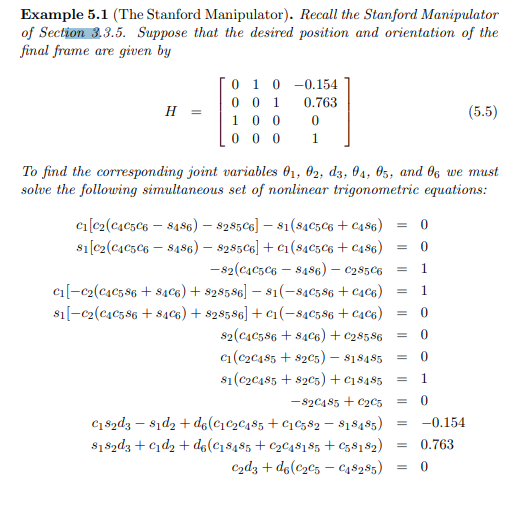

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.


% %H11 = solve(T04(1,1)==T04_Re(1,1)) % gives an approximate value for t2 that then needs to be inserted back into the cosine
% H = ones(4)
% H11 = double(subs(T04(1,1),solve(T04(1,1)==T04_Re(1,1))));
% H11 = H11(1)
% H11 = double(subs(T04(1,1),solve(T04(1,1)==T04_Re(1,1))));
% H12 = double(subs(T04(1,2),solve(T04(1,2)==T04_Re(1,2))));
% %H13 = double(subs(T04(1,3),solve(T04(1,3)==T04_Re(1,3)))) % value is 0
% 
% H14 = double(subs(T04(1,4),solve(T04(1,4)==T04_Re(1,4))));
% H21 = double(subs(T04(2,1),solve(T04(2,1)==T04_Re(2,1))));
% H22 = double(subs(T04(2,2),solve(T04(2,2)==T04_Re(2,2))));
% H23 = double(subs(T04(2,3),solve(T04(2,3)==T04_Re(2,3))));
% H24 = double(subs(T04(2,4),solve(T04(2,4)==T04_Re(2,4))));
% H31 = double(subs(T04(3,1),solve(T04(3,1)==T04_Re(3,1))));
% H32 = double(subs(T04(3,2),solve(T04(3,2)==T04_Re(3,2))));
% H33 = double(subs(T04(3,3),solve(T04(3,3)==T04_Re(3,3))));
% H34 = double(subs(T04(3,4),solve(T04(3,4)==T04_Re(3,4))));
% %H41 = double(subs(T04(4,1),solve(T04(4,1)==T04_Re(4,1))))
% %H42 = double(subs(T04(4,2),solve(T04(4,2)==T04_Re(4,2))))
% %H43 = double(subs(T04(4,3),solve(T04(4,3)==T04_Re(4,3))))
% %H44 = double(subs(T04(4,4),solve(T04(4,4)==T04_Re(4,4))))
% 
% H(1,1) = H11(1);
% H(1,2) = H12(1);
% H(1,3) = 0;
% H(1,4) = H14(1);
% H(2,1) = H21(1);
% H(2,2) = H22(1);
% H(2,3) = H23(1);
% H(2,4) = H24(1);
% H(3,1) = H31(1);
% H(3,2) = H32(1);
% H(3,3) = H33(1);
% H(3,4) = H34(1);
% H(4,1) = 0;
% H(4,2) = 0;
% H(4,3) = 0;
% H(4,4) = 1;
% 
% 
% H



## **Problem 3:**

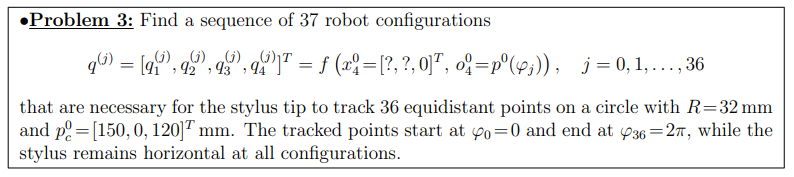


% origin of the circle to be traced
xc = 150;
yc = 0;
zc = 120;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832


dy = cos(angles);
dz = sin(angles);

x = zeros(1,length(angles))

x =   151.0000  150.9848  150.9397  150.8660  150.7660  150.6428  150.5000  150.3420  150.1736  150.0000  149.8264  149.6580  149.5000  149.3572  149.2340  149.1340  149.0603  149.0152  149.0000  149.0152  149.0603  149.1340  149.2340  149.3572  149.5000  149.6580  149.8264  150.0000  150.1736  150.3420  150.5000  150.6428  150.7660  150.8660  150.9397  150.9848  151.0000


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = yc + dy
z = zc + dz

z =   120.0000  120.1736  120.3420  120.5000  120.6428  120.7660  120.8660  120.9397  120.9848  121.0000  120.9848  120.9397  120.8660  120.7660  120.6428  120.5000  120.3420  120.1736  120.0000  119.8264  119.6580  119.5000  119.3572  119.2340  119.1340  119.0603  119.0152  119.0000  119.0152  119.0603  119.1340  119.2340  119.3572  119.5000  119.6580  119.8264  120.0000



[t1,t2,t3] = theta(x,y,z)

t1 =     1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708


t2 =    -0.4059   -0.4063   -0.4071   -0.4082   -0.4096   -0.4113   -0.4131   -0.4150   -0.4171   -0.4191   -0.4212   -0.4231   -0.4248   -0.4263   -0.4275   -0.4285   -0.4291   -0.4293   -0.4292   -0.4288   -0.4280   -0.4268   -0.4254   -0.4238   -0.4220   -0.4200   -0.4180   -0.4159   -0.4139   -0.4120   -0.4103   -0.4088   -0.4076   -0.4066   -0.4060   -0.4058   -0.4059


t3 =     0.1016    0.1027    0.1033    0.1033    0.1027    0.1016    0.0999    0.0977    0.0952    0.0923    0.0891    0.0858    0.0825    0.0792    0.0760    0.0731    0.0706    0.0684    0.0668    0.0656    0.0650    0.0650    0.0656    0.0668    0.0684    0.0706    0.0731    0.0760    0.0792    0.0825    0.0858    0.0891    0.0923    0.0952    0.0977    0.0999    0.1016



%t1 = theta1(x,y);
%t3 = theta3(x,y,z);
%t2 = theta2(x,y,z,t3);
t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

t4 =     1.8751    1.8744    1.8746    1.8757    1.8777    1.8805    1.8840    1.8881    1.8927    1.8977    1.9028    1.9080    1.9131    1.9179    1.9223    1.9261    1.9293    1.9317    1.9333    1.9340    1.9337    1.9326    1.9306    1.9278    1.9243    1.9202    1.9156    1.9107    1.9055    1.9003    1.8953    1.8905    1.8861    1.8823    1.8791    1.8767    1.8751



% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));



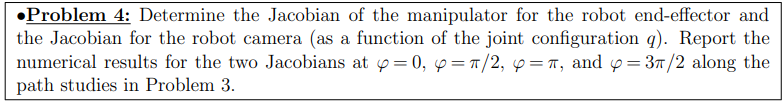

% if you need help figuring out the angles contact me
